% Define parameters
t1 = 1;
t2 = 0.1;
m = 0.2;
w = 0;
Nx = 50;
Ny = 50; % needs to be even to have a whole # of unit cells!
EF = 0;

%{
% Diagonalise full hamiltonian
H = H_matrix(m, w, t1, t2, Ny, Nx);
[Estates,Evals] = eig(H);
%}

Evals_array = readmatrix('~/Documents/PhD/EBL2/python_files/eigenvalues.csv');
Evals = diag(Evals_array);
Estates = readmatrix('~/Documents/PhD/EBL2/python_files/eigenvectors_mat.csv');

% Construct matrices composing the chern marker
p_prod = zeros(Nx*Ny,Nx*Ny);
q_prod = zeros(Nx*Ny,Nx*Ny);
for i=1:Nx*Ny
    if Evals(i,i) < EF
        p_prod = p_prod + Estates(:,i) * ctranspose(Estates(:,i));
    else
        q_prod = q_prod + Estates(:,i) * ctranspose(Estates(:,i));
    end
end

x_op_elements = floor((0:Ny*Nx-1)/Ny);
x_op = diag(x_op_elements)

x_op =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_op_elements = repmat((0:Ny-1), 1, Nx);
y_op = diag(y_op_elements)

y_op =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     3     0     0     0     0     0     0     0     0     0     0     0


%in_matrix = p_prod * x_op * (eye(Nx*Ny) - p_prod) * y_op * p_prod
in_matrix = p_prod * x_op * q_prod * y_op * p_prod

in_matrix =    0.3776 + 0.9925i   0.6288 - 0.1373i  -0.3219 - 1.0248i  -0.5165 - 0.0689i  -0.1526 + 0.7591i   0.7761 + 0.0332i   0.0929 - 0.8605i  -0.6154 - 0.1767i  -0.2402 + 0.6611i   0.7776 + 0.1514i   0.1789 - 0.7920i  -0.6125 - 0.2664i  -0.2887 + 0.6235i   0.7623 + 0.2276i   0.2381 - 0.7643i  -0.5913 - 0.3251i  -0.3320 + 0.5963i   0.7438 + 0.2873i   0.2918 - 0.7422i  -0.5670 - 0.3699i  -0.3717 + 0.5697i   0.7227 + 0.3394i   0.3417 - 0.7190i  -0.5410 - 0.4083i  -0.4081 + 0.5417i   0.6988 + 0.3873i   0.3885 - 0.6930i  -0.5129 - 0.4431i  -0.4415 + 0.5119i   0.6717 + 0.4324i   0.4325 - 0.6639i  -0.4824 - 0.4755i  -0.4716 + 0.4800i   0.6415 + 0.4763i   0.4737 - 0.6318i  -0.4492 - 0.5071i  -0.4966 + 0.4471i   0.6091 + 0.5216i   0.5106 - 0.5981i  -0.4133 - 0.5419i  -0.5083 + 0.4161i   0.5820 + 0.5812i   0.5352 - 0.5698i  -0.3824 - 0.6008i  -0.4643 + 0.3831i   0.6524 + 0.7197i   0.4868 - 0.5664i  -0.4858 - 0.7787i  -0.2590 + 0.1023i   1.8653 + 0.5167i
  -0.4848 + 0.1827i   0.0908 + 0.2596


xvals = 0:Nx-1;
yvals = 0:Ny-1;
[X,Y] = meshgrid(xvals,yvals);
Z = arrayfun(@(x,y) Chern_marker(x, y, Ny, Estates, in_matrix), X, Y);

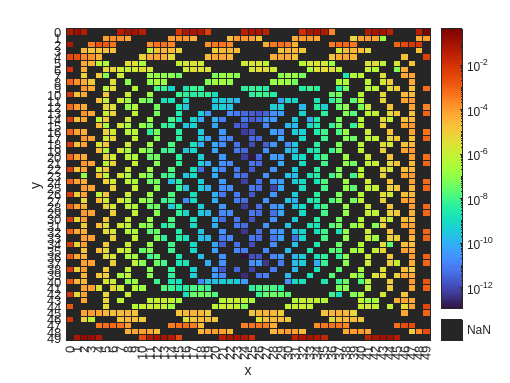

figure;
heatmap(xvals, yvals, Z)
xlabel('x')
ylabel('y')
colormap('turbo');
set(gca, "ColorScaling","log")

%clim([-0.01,0.01]);
drawnow;

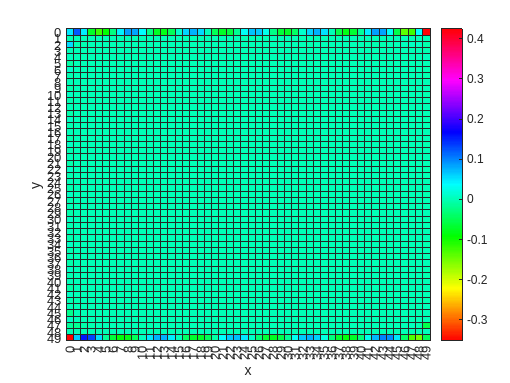


figure;
heatmap(xvals, yvals, Z)
xlabel('x')
ylabel('y')
colormap(['hsv']);

%clim([-0.2,0.2]);
drawnow;

%{
figure;
surf(X,Y,Z)
colorbar
set(gca,'ColorScale','log')
%}

function Mass = Mass(M, N)
    % Initialize the Mass matrix
    Mass = diag(-M .* (-1).^(1:N));
end

function H0 = H0(t1, t2, N)
    % Initialize the H0 matrix
    H0 = -(diag(t1 * ones(1, N-1), 1) + diag(t1 * ones(1, N-1), -1) + ...
        diag(1i * t2 * (-1).^floor((0:N-3)/2), 2) + diag(-1i * t2 * (-1).^floor((0:N-3)/2), -2));
end

function H1 = H1(t1, t2, N)
    % Initialize the H1 matrix
    list1 = repmat([0, 0, t1, 0], 1, ceil(N / 4));
    list2 = repmat([t1, 0, 0, 0], 1, ceil(N / 4));
    list3 = repmat([0, -1i * t2, 1i * t2, 0], 1, ceil(N / 4));
    list4 = repmat([1i * t2, 0, 0, -1i * t2], 1, ceil(N / 4));
    H1 = -(diag(1i * t2 .* (-1).^(1:N)) + diag(list1(1:N-1), 1) + diag(list2(1:N-1), -1) + ...
        diag(list3(1:N-2), 2) + diag(list4(1:N-2), -2));
end

function V = V(N)
    V = diag(-1+2.*rand(1,N));
end

function H_matrix = H_matrix(M, W, T1, T2, Ny, Nx)
    % Initialize matrices H0, H1, and H2
    H0_matrix = H0(T1, T2, Ny) + Mass(M,Ny);
    H1_matrix = H1(T1, T2, Ny);
    H2_matrix = ctranspose(H1(T1, T2, Ny));
    
    % Initialise cells
    H0_cell = cell(1,Nx);
    H1_cell = cell(1,Nx);
    H2_cell = cell(1,Nx);
    Vxy = cell(1,Nx);
    % Generate matrix cells
    for i = 1:Nx
        H0_cell{i} = H0_matrix;
        H1_cell{i} = H1_matrix;
        H2_cell{i} = H2_matrix;
        Vxy{i} = W * V(Ny);
    end


    % Construct the block diagonal matrix
    H_block = blkdiag(H0_cell{:}) + blkdiag(Vxy{:});

    % Construct sparse matrices for H1 and H2

    H1_sparse_a = blkdiag(H1_cell{1:end-1});
    H1_sparse_b = [H1_sparse_a zeros(size(H1_sparse_a,1),Ny)];
    H1_sparse = [zeros(Ny, size(H1_sparse_b, 2)); H1_sparse_b];

    H2_sparse_a = blkdiag(H1_cell{1:end-1});
    H2_sparse_b = [zeros(size(H2_sparse_a,1),Ny) H2_sparse_a];
    H2_sparse = [H2_sparse_b; zeros(Ny, size(H2_sparse_b, 2))];

    % Assemble the final matrix
    H_matrix = H_block + H1_sparse + H2_sparse;
end

function Chern_marker = Chern_marker(x, y, Ny, Psi, inner_matrix)
    % (X,Y) = position of A site, (X,Y+1) = position of B site
    m = 1 + y + Ny * x;
    
    % evaluate chern marker for the edge state only!
    %Chern_marker = 4 * pi * imag(Psi(m,1250)^2 * inner_matrix(m,m));

    Chern_marker = 4 * pi * imag(inner_matrix(m,m));

    %{
    element = cell(1,size(Psi,1));
    for j = 1:size(Psi,1)/2
        element{j} = Psi(m,j)^2 * inner_matrix(m,m);
    end
    Chern_marker = 4 * pi * imag(sum([element{:}]));
    %}
end